tic
clc;
clear;
close all;

## Model call

model=CreateModel();

model.n=3;  % number of Handle Points

CostFunction=@(x) MyCost(x,model);    % Cost Function

nVar=model.n;       % Number of Decision Variables

VarSize=[1 nVar];   % Size of Decision Variables Matrix

VarMin.x=model.xmin;           % Lower Bound for Variables
VarMax.x=model.xmax;           % Upper Bound for Variables
VarMin.y=model.ymin;           % Lower Bound for Variables
VarMax.y=model.ymax;           % Upper Bound for Variables

## Parameters

MaxIt=80;          % Maximum Number of Iterations

nPop=150;           % Population Size (Swarm Size)

w=1;                % Inertia Weight
wdamp=0.98;         % Inertia Weight Damping Ratio
c1=1.5;             % Personal Learning Coefficient
c2=1.5;             % Global Learning Coefficient

% % Constriction Coefficient
% phi1=2.05;
% phi2=2.05;
% phi=phi1+phi2;
% chi=2/(phi-2+sqrt(phi^2-4*phi));
% w=chi;               % Inertia Weight
% wdamp=1;             % Inertia Weight Damping Ratio
% c1=chi*phi1;         % Personal Learning Coefficient
% c2=chi*phi2;         % Global Learning Coefficient

alpha=0.1;
VelMax.x=alpha*(VarMax.x-VarMin.x);    % Maximum Velocity
VelMin.x=-VelMax.x;                    % Minimum Velocity
VelMax.y=alpha*(VarMax.y-VarMin.y);    % Maximum Velocity
VelMin.y=-VelMax.y;                    % Minimum Velocity

## Initialization

% Create Empty Particle Structure
empty_particle.Position=[];
empty_particle.Velocity=[];
empty_particle.Cost=[];
empty_particle.Sol=[];
empty_particle.Best.Position=[];
empty_particle.Best.Cost=[];
empty_particle.Best.Sol=[];

% Initialize Global Best
GlobalBest.Cost=inf;

% Create Particles Matrix
particle=repmat(empty_particle,nPop,1);

% Initialization Loop
for i=1:nPop
    
    if i > 1
    % Initialize Position
        particle(i).Position=CreateRandomSolution(model);
    else
        % Straight line from source to destination
        xx = linspace(model.xs, model.xt, model.n+2);
        yy = linspace(model.ys, model.yt, model.n+2);
        particle(i).Position.x = xx(2:end-1);
        particle(i).Position.y = yy(2:end-1);
    end
    
    % Initialize Velocity
    particle(i).Velocity.x=zeros(VarSize);
    particle(i).Velocity.y=zeros(VarSize);
    
    % Evaluation
    [particle(i).Cost, particle(i).Sol]=CostFunction(particle(i).Position);
    
    % Update Personal Best
    particle(i).Best.Position=particle(i).Position;
    particle(i).Best.Cost=particle(i).Cost;
    particle(i).Best.Sol=particle(i).Sol;
    
    % Update Global Best
    if particle(i).Best.Cost<GlobalBest.Cost
        
        GlobalBest=particle(i).Best;
        
    end
    
end

% Array to Hold Best Cost Values at Each Iteration
BestCost=zeros(MaxIt,1);

## PSO Main Loop

for it=1:MaxIt
    
    for i=1:nPop
        
        % x Part
        
        % Update Velocity
        particle(i).Velocity.x = w*particle(i).Velocity.x ...
            + c1*rand(VarSize).*(particle(i).Best.Position.x-particle(i).Position.x) ...
            + c2*rand(VarSize).*(GlobalBest.Position.x-particle(i).Position.x);
        
        % Update Velocity Bounds
        particle(i).Velocity.x = max(particle(i).Velocity.x,VelMin.x);
        particle(i).Velocity.x = min(particle(i).Velocity.x,VelMax.x);
        
        % Update Position
        particle(i).Position.x = particle(i).Position.x + particle(i).Velocity.x;
        
        % Velocity Mirroring
        OutOfTheRange=(particle(i).Position.x<VarMin.x | particle(i).Position.x>VarMax.x);
        particle(i).Velocity.x(OutOfTheRange)=-particle(i).Velocity.x(OutOfTheRange);
        
        % Update Position Bounds
        particle(i).Position.x = max(particle(i).Position.x,VarMin.x);
        particle(i).Position.x = min(particle(i).Position.x,VarMax.x);
        
        % y Part
        
        % Update Velocity
        particle(i).Velocity.y = w*particle(i).Velocity.y ...
            + c1*rand(VarSize).*(particle(i).Best.Position.y-particle(i).Position.y) ...
            + c2*rand(VarSize).*(GlobalBest.Position.y-particle(i).Position.y);
        
        % Update Velocity Bounds
        particle(i).Velocity.y = max(particle(i).Velocity.y,VelMin.y);
        particle(i).Velocity.y = min(particle(i).Velocity.y,VelMax.y);
        
        % Update Position
        particle(i).Position.y = particle(i).Position.y + particle(i).Velocity.y;
        
        % Velocity Mirroring
        OutOfTheRange=(particle(i).Position.y<VarMin.y | particle(i).Position.y>VarMax.y);
        particle(i).Velocity.y(OutOfTheRange)=-particle(i).Velocity.y(OutOfTheRange);
        
        % Update Position Bounds
        particle(i).Position.y = max(particle(i).Position.y,VarMin.y);
        particle(i).Position.y = min(particle(i).Position.y,VarMax.y);
        
        % Evaluation
        [particle(i).Cost, particle(i).Sol]=CostFunction(particle(i).Position);
        
        % Update Personal Best
        if particle(i).Cost<particle(i).Best.Cost
            
            particle(i).Best.Position=particle(i).Position;
            particle(i).Best.Cost=particle(i).Cost;
            particle(i).Best.Sol=particle(i).Sol;
            
            % Update Global Best
            if particle(i).Best.Cost<GlobalBest.Cost
                GlobalBest=particle(i).Best;
            end
            
        end
        
        
    end
end
    % Update Best Cost Ever Found
   BestCost(it)=GlobalBest.Cost;
    
    % Inertia Weight Damping
    w=w*wdamp;
    %xx
    %yy
    
    % Show Iteration Information
    if GlobalBest.Sol.IsFeasible
        Flag=' *';
    else
        Flag=[', Violation = ' num2str(GlobalBest.Sol.Violation)];
    end
    disp(['Iteration ' num2str(it) ': Best Cost = ' num2str(BestCost(it)) Flag]);

Iteration 80: Best Cost = 8.421 *


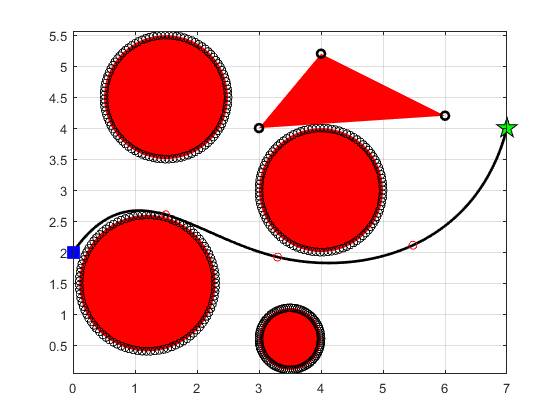

    
    % Plot Solution
    figure(1);
    SolnPlot(GlobalBest.Sol,model);

    %GlobalBest.Sol;
    timeElapsed = toc

timeElapsed = 27.5839

    pause(0.01);
    

## Results

    %{
figure;
plot(BestCost,'LineWidth',2);
xlabel('Iteration');
ylabel('Best Cost');
grid on;
    %}